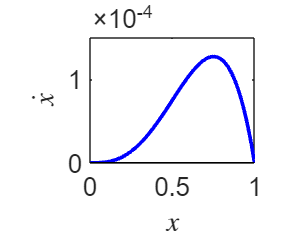

% Non-linear Stochastic Evolutionary Dynamics - PGG
% Shayan Firouzian H.

clear all

% Define Parameters

G=5;
max_r=2*G;
r     =5;
p     =0.5;
delta =0.2;

pc=zeros(101,1);
for i=1:101
    x=0.01*(i-1);
    pc(i,1)=x * (1 - x) * tanh(((r / G) * (p * (1 + delta * x) ^ (G - 1) + (1 - p) * (1 - delta * x) ^ (G - 1)) - 1)*0.005);
end

fig=figure;
bb=0:0.01:1;
plot(bb,pc(:,1),'Color', 'b','LineWidth',2)
xlim=get(gca,'Xlim'); 


line([0, 1], [0, 0], 'Color', 'k', 'LineStyle', '-','LineWidth',1);
ylabel('$\dot{x}$','Interpreter','latex');
xlabel('${x}$','Interpreter','latex');


fig.Units = "pixels";
fig.Position = [119,686,204,175]; 
set(gca, 'FontName', 'Arial');
set(gca, 'FontSize', 14); 